# 1.2.16. Выделение тренда

**Самостоятельная работа**

Выделите тренд на температурных данных и пронаблюдайте эффект глобального потепления на примере Москвы.

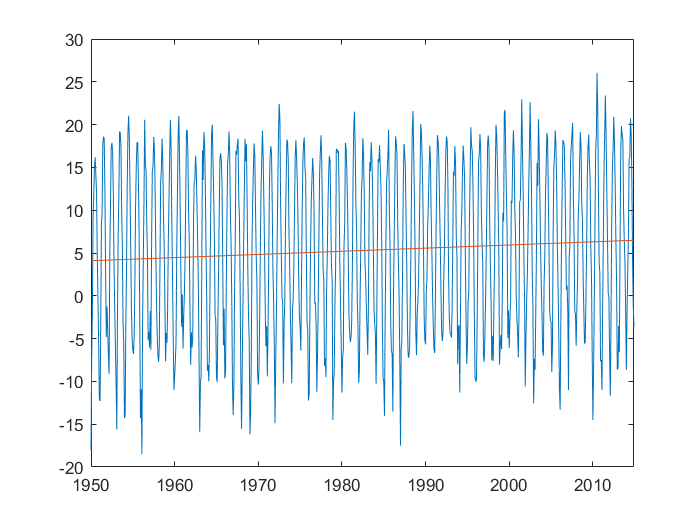

## Чтение данных

1. Считайте данные из файла `tempmonth.csv` в переменную `T` типа `table` (подсказка: `readrable()`)

2. Постройте график среднемесячной температуры (`TAVG`) от времени (`DATE`). Переменная `h1` должна ссылаться на график (подсказка: `plot()`)

На графике видны сезонные колебания средней температуры в Москве за несколько десятилетий.

## Подготовка данных

Чтобы выделить тренд, нужно аппроксимировать данные прямой (полиномом первого порядка). Для этого в MATLAB есть встроенные функции `polyfit()`, `polyval()`

3. В переменную `dur` запишите вектор времени, прошедшего с момента первого измерения до каждого из элементов столбца `DATE`. Должен получиться монотонно возрастающий вектор типа `duration` (подсказка: `-`, `(1)`)

4. В столбец `YEARS` таблицы `T` запишите вектор количества лет, которое содержится в векторе `dur` (подсказка: `years()`)

## Построение тренда

5. С помощью функции `polyfit()` аппроксимируйте сигнал `TAVG` от `YEARS` полиномом первой степени. Результат запишите в переменную `p` (подсказка: `polyfit(...,...,1)`)

Ответьте на вопрос, почему получился вектор из двух элементов. Как это соответствует полиному первого порядка?

6. С помощью функции `polyval()` получите вектор значений аппроксимированного сигнала по модели `p` для вектора времени `YEARS`. Результат запишите в столбец TT таблицы T (подсказка: `polyval(...,...)`)

7. Постройте линию тренда `TT` от `DATE`, наложив её на график `h1`, построенный ранее (подсказка: `hold` ..., `plot()`). На график тренда должна ссылаться переменная `h2`

## Анализ тренда

8. В переменную `r` запишите диапазон изменения тренда `TT` (подсказка: `end`, `1`)

9. В переменную `t` запишите временной интервал вашей выборки в годах по столбцу `YEARS `(подсказка: `end`, `1`)

Таким образом, вы видите, что средняя температура в Москве выросла на `r` градусов за `t` лет.

10. Скорость возрастания температуры запишите в переменную `v` (градус/год)

*2018 © ЦИТМ Экспонента*